# Algoritmos Numéricos por Computadora

# Primer parcial - Primavera 2024

Sube tu archivo resultado a Canvas $\to$ Examen Parcial 1 antes de las 11:30am.

Tu archivo debe mostrar claramente todos los resultados.

Cada pregunta vale 5 puntos.

El script debe correr con las funciones que agregues al final.

Asegúrate de guardar el archivo frecuentemente.

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

El artículo 29 del Reglamento de Alumnos establece que "se calificará como no acreditada (N.A.) cualquier materia cuando el alumno incurra en alguna práctica fraudulenta".

## 1. Punto flotante IEEE-754 doble precisión

a) Encuentra los exponentes be y e del número 1. Puedes usar la función bin2dec.

uno = 1

uno = 1

format hex
uno

uno =    3ff0000000000000


format default
b = '0011111111110000000000000000000000000000000000000000000000000000';
be = bin2dec(b(2:12))

be = 1023

e = be - 1023

e = 0

b) Encuentra el exponentes be y e del número 2. Puedes usar la función bin2dec.

dos = 2

dos = 2

format hex
dos

dos =    4000000000000000


format default
b = '0100000000000000000000000000000000000000000000000000000000000000';
be = bin2dec(b(2:12))

be = 1024

e = be - 1023

e = 1

c) ¿Cuántos números pueden representarse de manera exacta en el intervalo [1,2) ?

numsEn12 = 2/eps(1)

numsEn12 = 9.0072e+15

d) ¿Cuántos números pueden representarse de manera exacta en el intervalo [2,4) ?

numsEn24 = 4/eps(2)

numsEn24 = 9.0072e+15

e) ¿Cuántos números (normalizados) pueden representarse de manera exacta en el intervalo (0,1) ?

minEn01 = 0+eps; %tomamos el minimo del intervalo
maxEn01 = 1-eps; %y el maximo del intervalo
diferencia = maxEn01 - minEn01;
numsEn01 = maxEn01/eps(diferencia) %obtenemos la distancia entre los dos

numsEn01 = 9.0072e+15

Usando tres algoritmos diferentes, calcula todas las  soluciones de la ecuación


$$f\left(x\right)=x+4\cos \left(x\right)=0$$


## 2. Raíces 1

Primero, gráfica la función para mostrar que existen tres (y solo tres) soluciones y observar en qué intervalos se encuentran.

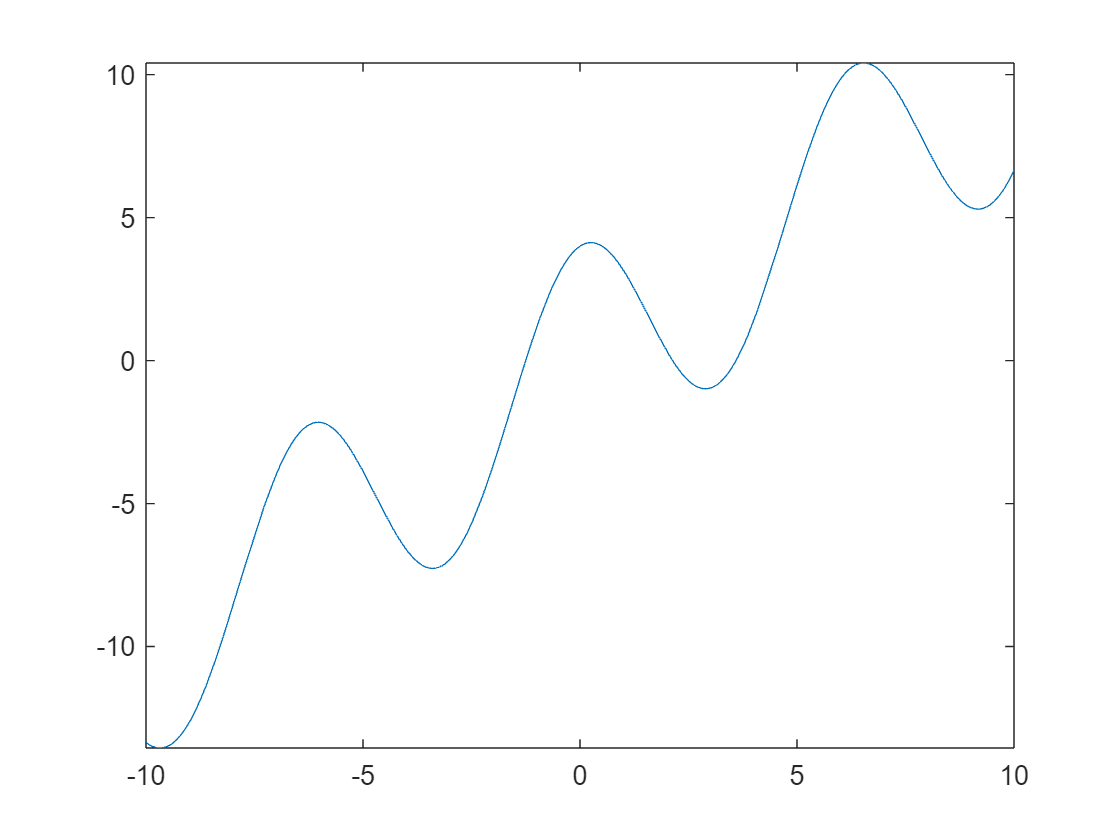

fx = @(x) x + 4.*cos(x);
fplot(fx, [-10 10])

Encuentra la primera raíz $x_1$ de la función usando el método de bisección o el de falsa posición.  

[root, iterations] = falsePosition(fx, -2, -0.5);
fprintf('Falsa posición - raiz: %f - iteraciones: %d', root, iterations);

Falsa posición - raiz: -1.252353 - iteraciones: 9

## 3. Raíces 2

Encuentra la segunda raíz $x_2$ de la función usando el método de la secante o el de Newton-Raphson.  

[root, iterations] = newtonRaphson(fx, 1);
fprintf('Newton-Raphson - raiz: %f - iteraciones: %d', root, iterations)

Newton-Raphson - raiz: 2.133332 - iteraciones: 6

## 4. Raíces 3

Encuentra la tercera raíz $x_3$ de la función usando el método de Muller o el de interpolación cuadrática inversa.  

[root, iterations] = ipi(fx, 3, 4, 5);
fprintf('IPI - raiz: %f - iteraciones: %d', root, iterations);

IPI - raiz: 3.595305 - iteraciones: 7

## 5. Algoritmo de Brent

Programa, al final del script,  el algortimo de Brent de manera eficiente y elegante. 

Pruébalo con 

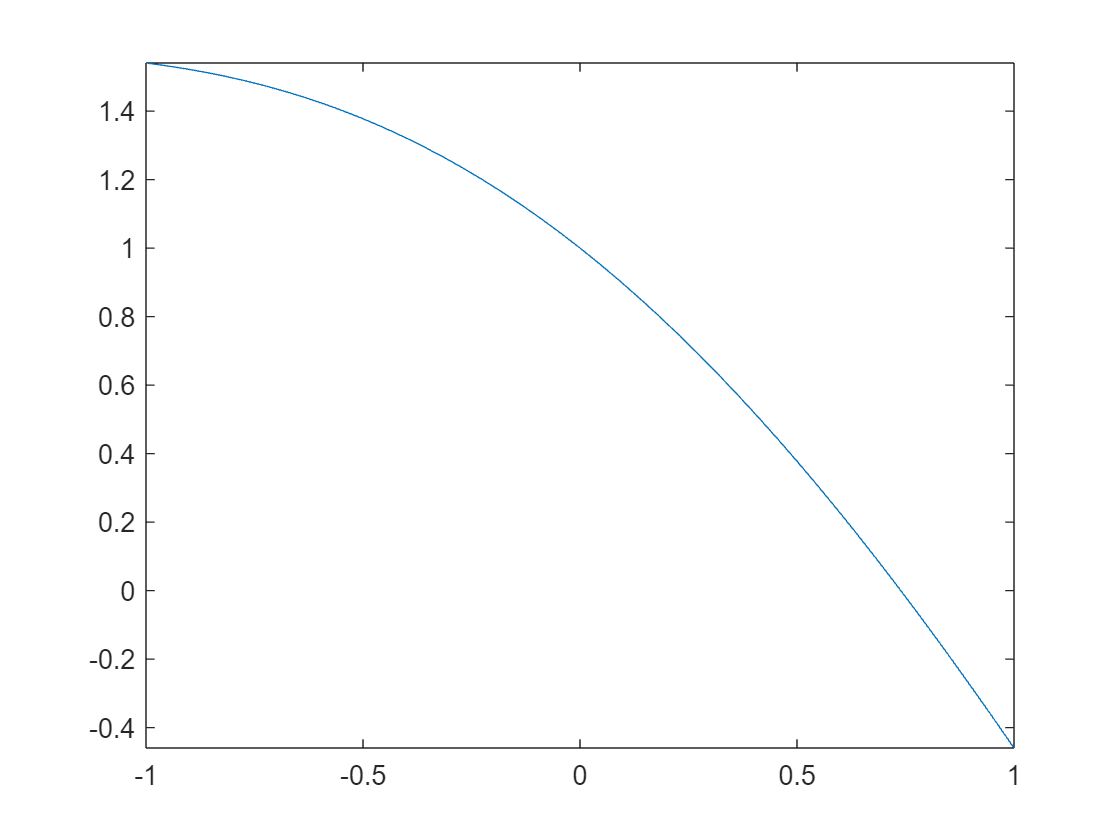

f = @(x) cos(x) - x;
fplot(f, [-1 1])

[root, iterations] = brent(f, -1, 1);
fprintf('Brent - raiz: %f - iteraciones: %d', root, iterations)

Brent - raiz: 0.739085 - iteraciones: 7

## 6. Aplicación 1

Un resorte presenta una fuerza de restauración dada por:


$$F=c_1 x+c_3 x^3 +c_5 x^5$$


donde $x$ es la compresión del resorte. 

Los valores de las constantes son

$c_1$ = 5.25 kg/cm,

$c_3$  = 0.60 kg/cm,

$c_5$  = 0.0118 kg/cm.

Si un peso $F=12\ldotp 5$kg se aplica al resorte, ¿cuánto se comprime (valor de $x$)?

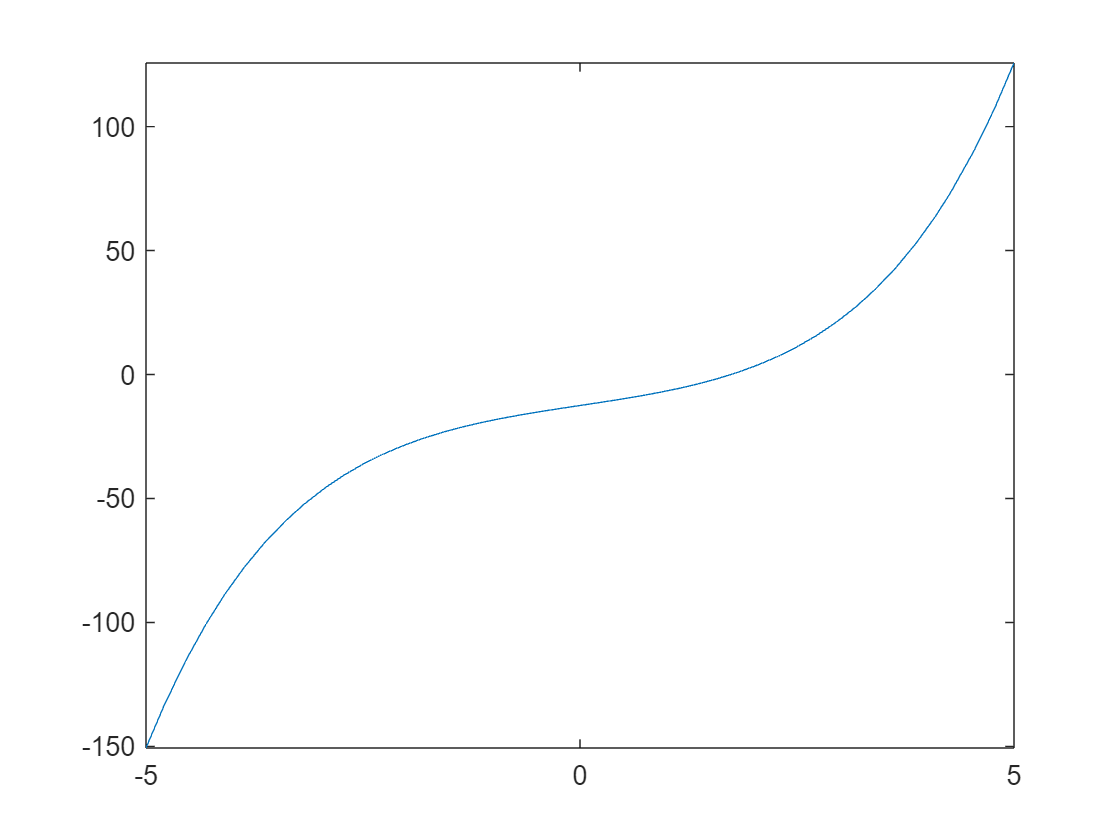

c1 = 5.25;      % kg/cm
c3 = 0.60;
c5 = 0.0118;
W = 12.5;       % kg

fx = @(x) c1.*x + c3.*x.^3 + c5.*x.^5 - W;
fplot(fx)

[result, i] = newtonRaphson(f, 1.5);
fprintf('La compresión del resorte es: %f cm', result)

La compresión del resorte es: 0.739085 cm

## 7. Aplicación 2

Se tiene un cañon que dispara proyectiles con una velocidad $v$ a un ángulo $\theta$. ¿A qué ángulo debe dispararse el cañon para pegar en el suelo a una distancia R?

Sabemos que la trayectoria del proyectil está dada por


$$x\left(t\right)=\left(v\;\cos \theta \right)t$$
 


$$y\left(t\right)=\left(v\;\sin \theta \right)-\frac{1}{2}g\;t^2$$


Resolviendo para $y$ como función de $x\;$se tiene


$$y\left(x\right)=x\left(\tan \theta \right)-\frac{1}{2}g{\left(\frac{x}{v\;\cos \theta }\right)}^2$$


donde el ángulo está dado en radianes.

Ahora el rango R es el valor de $x$ cuando $y=0$, un problema de raíces, claro.

Si $v=55\frac{m}{s}$ y queremos $x=250$, ¿cuánto debe valer $\theta$?

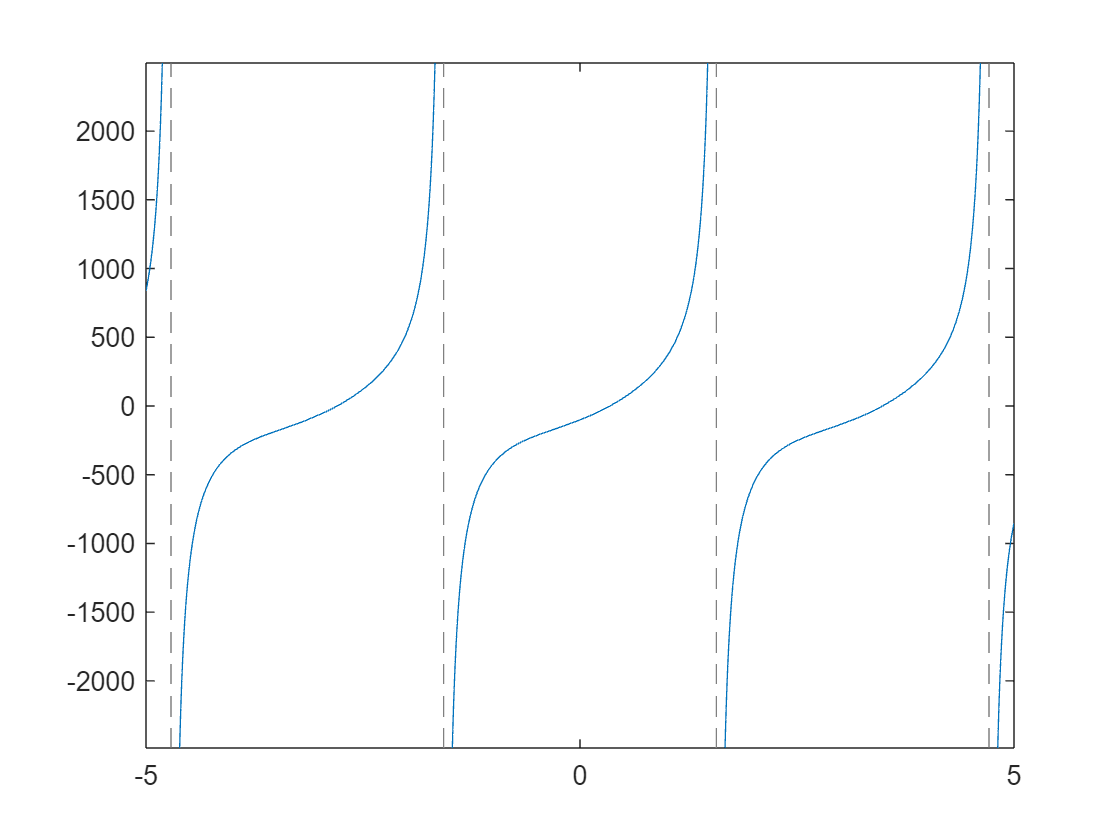

v = 55;
x = 250;
g = 9.81;
yx = @(theta) x.*tan(theta) - 1/2*g.*((x/v.*cos(theta)).^2);
fplot(yx)

[rads, i] = newtonRaphson(yx, 0.2);

Convierte el resultado a grados

rads

rads = 0.3447

ang = rad2deg(rads)

ang = 19.7519

Compara tu resultado con el valor exacto


$$\theta =\frac{1}{2}\sin^{-1} \left(\frac{R\;g}{v^2 }\right)$$


radsExactos = 1/2*asin(x*g/v^2)

radsExactos = 0.4727

angExacto = rad2deg(radsExactos)

angExacto = 27.0843

diferenciaRads = abs(radsExactos - rads)

diferenciaRads = 0.1280

diferenciaAng = abs(angExacto - ang)

diferenciaAng = 7.3324

Inserta aquí las funciones que utilices.  

function [x, i] = brent(f, x1, x2, itMax, rTol)
    fa = f(x1);
    fb = f(x2);

    if sign(fa) == sign(fb)
        error('f(a) * f(b) is not true');
    end

    if ~exist("itMax","var")
        itMax = 100;
    end

    if ~exist("rTol", "var")
        rTol = eps;
    end

    i = 0;
    condition = true;
    f1 = f(x1);
    f2 = f(x2);
    x3 = 0.5*(x1+x2);
    if f1 ~= 0 && f2 ~= 0
        while condition
            f3 = f(x3);
            denom = (f2 - f1)*(f3 - f1)*(f2 - f3);
            numer = x3*(f1-f2)*(f2-f3+f1) ...
                + f2*x1*(f2-f3) + f1*x2*(f3-f1);

            if denom == 0; dx = x2+x1; 
            else; dx = f3*numer/denom; end

            x = x3 + dx;
            if (x2-x)*(x-x1) < 0
                dx = 0.5*(x2-x1);
                x = x1 + dx;
            end

            if x < x3
                x2 = x3; 
                f2 = f3;
            else
                x1 = x3;
                f1 = f3;
            end
            
            x3 = x;
            i = i + 1;
            condition = abs(f3) > rTol && i < itMax;
        end
    end

    if i == itMax
        warning('brent:IterationLimitReached', 'The iteration limit was reached')
    end
end

function [x, i] = falsePosition(f, a, b, rTol, itMax)
    signA = sign(f(a));

    if sign(f(b)) == signA
        error('f(a)*f(b) is not true');
    end

    if ~exist("itMax", "var")
        itMax = 100;
    end

    if ~exist("rTol", "var")
        rTol = eps;
    end

    i = 1;
    fa = f(a);
    fb = f(b);
    x = (a*fb - b*fa)/(fb - fa);
    condicion = true;
    while condicion
        if sign(f(x)) == signA
            b = x;
        else
            a = x;
        end
        fa = f(a);
        fb = f(b);
        xp = x;
        x = (a*fb - b*fa)/(fb - fa);
        i = i + 1;
        condicion = abs((x-xp)/x) > rTol && i < itMax;
    end

    if i == itMax
        warning('falsePosition:IterationLimitReached', 'The iteration limit was reached')
    end
end

function [x, i] = newtonRaphson(f, p, itMax, rTol)
    h = 1e-6;
    df = abbreviatedCentralFirstDerivative(f, p, h);

    if ~exist("itMax", "var")
        itMax = 100;
    end

    if ~exist("rTol", "var")
        rTol = eps;
    end
    
    x = p - f(p)/df;
    i = 0;
    condicion = true;
    while condicion
        xPrev = x;
        df = abbreviatedCentralFirstDerivative(f, x, h);
        x = x - f(x)/df;

        i = i + 1;
        condicion = abs((x-xPrev)/x) > rTol && i < itMax;
    end

    if i == itMax
        warning('newtonRaphson:IterationLimitReached', 'The iteration limit was reached')
    end
end

function df = abbreviatedCentralFirstDerivative(f, x, h)
    df = (f(x+h) - f(x-h))/(2*h);
end

function [x, i] = ipi(f, x1, x2, x3, rTol, itMax)
    if ~exist("itMax", 'var')
        itMax = 100;
    end
    
    if ~exist('rTol','var')
        rTol = eps;
    end
    
    f1 = f(x1);
    f2 = f(x2);
    i = 0;
    condicion = true;
    while condicion
        f3 = f(x3);
        p = polyfit([f1, f2, f3], [x1, x2, x3], 2);
        x = polyval(p, 0);
        x1 = x2;    f1 = f2;
        x2 = x3;    f2 = f3;
        x3 = x;
             
        i = i+1;
        condicion = abs((x - x2)/x) > rTol && i < itMax;
    end

    if i == itMax
        warning('ipi:IterationLimitReached', 'The iteration limit was reached')
    end
end